# 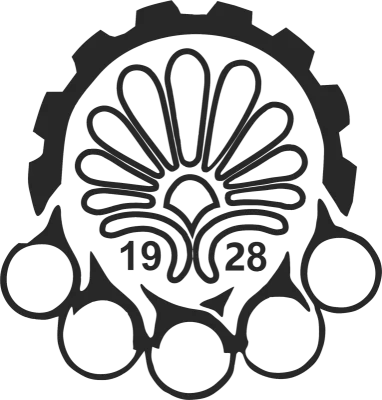

### Amirkabir University of Technology

### (Tehran Polytechnic)

## Department of Mechanical Engineering

**CFD Final Project**

# Lid-Driven Problem Solution Using SIMPLE Method

**By**

## Mohsen Afsharian

400126096

**Supervisor**

## Dr. Hamid Naderan

clear
close all
clc
tic

## 1.Generating Problem Domain

for k=1:4
if k<3
    N=[5 9 17 21 33];
elseif k==3 
    N=[33 51 65 91 129];
else
    N=[111 121 131 141 161];
end   % no_of_points
length = 1;
for l=1:5
h = length/(N(l)-1);
x = 0:h:length; %X domain span
y = 0:h:length; %Y domain span
Re=[1 10 100 500];
nu=1/Re(k);

## 2.Governing Equations

### 2.1. x direction momentum equation:


$$u\frac{\partial u}{\partial x}+v\frac{\partial u}{\partial y}=-\frac{\partial P}{\partial x}+\frac{1}{\mathrm{Re}}\left(\frac{\partial^2 u}{\partial x^2 }+\frac{\partial^2 u}{\partial y^2 }\right)$$


### 2.2. y direction momentum equation:


$$u\frac{\partial v}{\partial x}+v\frac{\partial v}{\partial y}=-\frac{\partial P}{\partial y}+\frac{1}{\mathrm{Re}}\left(\frac{\partial^2 v}{\partial x^2 }+\frac{\partial^2 v}{\partial y^2 }\right)$$


### 2.3. Continuity equation:


$$\frac{\partial u}{\partial x}+\frac{\partial v}{\partial y}=0$$


## 3. Discretization

### 3.1. Momentum Equations Discretization

Consider the staggerted mesh shown in figure 1. Black lines show cell boundaries, red arrows show u, green arrows show v and blue points show pressure. by integrating x momentum equation in highlighted control volume:

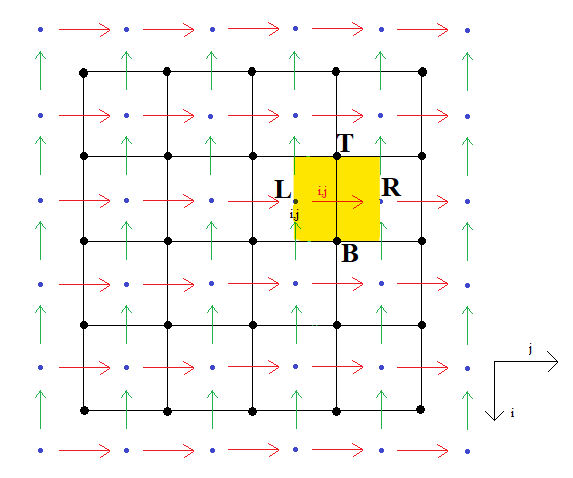

Figure 1


$$\int_B^T \int_L^R u\frac{\partial u}{\partial x}\mathrm{dxdy}=\left\lbrack u_R \left(\frac{u_{i,j} +u_{i,j+1} }{2}\right)-u_L \left(\frac{u_{i,j} +u_{i,j-1} }{2}\right)\right\rbrack \Delta y\;,\;\;\;\;u_R =\frac{u_{i,j} +u_{i,j+1} }{2},\;u_L =\frac{u_{i,j} +u_{i,j-1} }{2}$$
 


$$\int_B^T \int_L^R v\frac{\partial u}{\partial y}\mathrm{dxdy}=\left\lbrack v_T \left(\frac{u_{i+1,j} +u_{i,j} }{2}\right)-v_B \left(\frac{u_{i,j} +u_{i-1,j} }{2}\right)\right\rbrack \Delta x\;,\;\;\;\;\;v_T =\frac{v_{i,j} +v_{i,j+1} }{2},v_B =\frac{v_{i+1,j} +v_{i+1,j+1} }{2}$$



$$\frac{1}{\mathrm{Re}}\int_B^T \int_L^R \frac{\partial^2 u}{\partial x^2 }\mathrm{dxdy}=\left\lbrack {\left(\frac{\partial u}{\partial x}\right)}_R -{\left(\frac{\partial u}{\partial x}\right)}_L \right\rbrack \Delta y=\frac{1}{\mathrm{Re}}\left\lbrack \frac{u_{i,j+1} -u_{i,j} }{\Delta x}-\frac{u_{i,j} -u_{i,j-1} }{\Delta x}\right\rbrack \Delta y$$



$$\frac{1}{\mathrm{Re}}\int_B^T \int_L^R \frac{\partial^2 u}{\partial y^2 }\mathrm{dxdy}=\left\lbrack {\left(\frac{\partial u}{\partial y}\right)}_T -{\left(\frac{\partial u}{\partial y}\right)}_B \right\rbrack \Delta y=\frac{1}{\mathrm{Re}}\left\lbrack \frac{u_{i-1,j} -u_{i,j} }{\Delta y}-\frac{u_{i,j} -u_{i+1,j} }{\Delta y}\right\rbrack \Delta x$$



$$-\int_B^T \int_L^R \frac{\partial P}{\partial x}=-\left(P_R -P_L \right)\Delta y=\left(P_{i,j} -P_{i,j+1} \right)\Delta y$$



$$\left\lbrack u_R \left(\frac{u_{i,j} +u_{i,j+1} }{2}\right)-u_L \left(\frac{u_{i,j} +u_{i,j-1} }{2}\right)\right\rbrack \Delta y+\left\lbrack v_T \left(\frac{u_{i+1,j} +u_{i,j} }{2}\right)-v_B \left(\frac{u_{i,j} +u_{i-1,j} }{2}\right)\right\rbrack \Delta x+$$

$$\left(P_{i,j+1} -P_{i,j} \right)\Delta y-\frac{1}{\mathrm{Re}}\left\lbrack \frac{u_{i,j+1} -u_{i,j} }{\Delta x}-\frac{u_{i,j} -u_{i,j-1} }{\Delta x}\right\rbrack \Delta y-\frac{1}{\mathrm{Re}}\left\lbrack \frac{u_{i+1,j} -u_{i,j} }{\Delta y}-\frac{u_{i,j} -u_{i-1,j} }{\Delta y}\right\rbrack \Delta x=0$$



$$\Delta x=\Delta y=h$$


Holding $u_{i,j}$ on the left hand side and other terms on the right hand side:


$$\left(\frac{u_R }{2}h-\frac{u_L }{2}h+\frac{v_T }{2}h-\frac{v_B }{2}h+\frac{4}{\mathrm{Re}}\right)u_{i,j} =\left(\frac{1}{\mathrm{Re}}-\frac{u_R }{2}h\right)u_{i,j+1} +\left(\frac{1}{\mathrm{Re}}+\frac{u_L }{2}h\right)u_{i,j-1} +\left(\frac{1}{\mathrm{Re}}-\frac{v_T }{2}h\right)u_{i+1,j} +\left(\frac{1}{\mathrm{Re}}+\frac{v_B }{2}h\right)u_{i-1,j} +\Delta {\mathrm{yP}}_{i,j} -\Delta {\mathrm{yP}}_{i,j+1}$$



$$a_1 u_{i,j} =a_L u_{i,j+1} +a_R u_{i,j-1} +a_T u_{i+1,j} +a_B u_{i-1,j} +d_1 \left(P_{i,j+1} -P_{i,j} \right)$$


samely for y-momentum equation:


$$\int_B^T \int_L^R u\frac{\partial v}{\partial x}\mathrm{dxdy}=\left\lbrack u_R \left(\frac{v_{i,j} +v_{i,j+1} }{2}\right)-u_L \left(\frac{v_{i,j} +v_{i,j-1} }{2}\right)\right\rbrack \Delta y\;,\;\;\;\;u_R =\frac{u_{i,j} +u_{i,j+1} }{2},\;u_L =\frac{u_{i,j} +u_{i,j-1} }{2}$$
 


$$\int_B^T \int_L^R v\frac{\partial v}{\partial y}\mathrm{dxdy}=\left\lbrack v_T \left(\frac{v_{i+1,j} +v_{i,j} }{2}\right)-v_B \left(\frac{v_{i,j} +v_{i-1,j} }{2}\right)\right\rbrack \Delta x\;,\;\;\;\;\;v_T =\frac{v_{i,j} +v_{i,j+1} }{2},v_B =\frac{v_{i+1,j} +v_{i+1,j+1} }{2}$$



$$\frac{1}{\mathrm{Re}}\int_B^T \int_L^R \frac{\partial^2 v}{\partial x^2 }\mathrm{dxdy}=\left\lbrack {\left(\frac{\partial v}{\partial x}\right)}_R -{\left(\frac{\partial v}{\partial x}\right)}_L \right\rbrack \Delta y=\frac{1}{\mathrm{Re}}\left\lbrack \frac{v_{i,j+1} -v_{i,j} }{\Delta x}-\frac{v_{i,j} -v_{i,j-1} }{\Delta x}\right\rbrack \Delta y$$



$$\frac{1}{\mathrm{Re}}\int_B^T \int_L^R \frac{\partial^2 u}{\partial y^2 }\mathrm{dxdy}=\left\lbrack {\left(\frac{\partial v}{\partial y}\right)}_T -{\left(\frac{\partial v}{\partial y}\right)}_B \right\rbrack \Delta y=\frac{1}{\mathrm{Re}}\left\lbrack \frac{v_{i+1,j} -v_{i,j} }{\Delta y}-\frac{v_{i,j} -v_{i-1,j} }{\Delta y}\right\rbrack \Delta x$$



$$-\int_B^T \int_L^R \frac{\partial P}{\partial y}=-\left(P_T -P_B \right)\Delta x=-\left(P_{i-1,j} -P_{i,j} \right)\Delta x$$


Holding $v_{i,j}$ on the left hand side and other terms on the right hand side:


$$\left(\frac{u_R }{2}h-\frac{u_L }{2}h+\frac{v_T }{2}h-\frac{v_B }{2}h+\frac{4}{\mathrm{Re}}\right)v_{i,j} =\left(\frac{1}{\mathrm{Re}}-\frac{u_R }{2}h\right)v_{i,j+1} +\left(\frac{1}{\mathrm{Re}}+\frac{u_L }{2}h\right)v_{i,j-1} +\left(\frac{1}{\mathrm{Re}}-\frac{v_T }{2}h\right)v_{i-1,j} +\left(\frac{1}{\mathrm{Re}}+\frac{v_B }{2}h\right)v_{i+1,j} +\Delta {\mathrm{xP}}_{i,j} -\Delta {\mathrm{xP}}_{i+1,j}$$



$$a_2 v_{i,j} =a_L v_{i,j+1} +a_R v_{i,j-1} +a_T v_{i-1,j} +a_B v_{i+1,j} +\Delta x\left(P_{i-1,j} -P_{i,j} \right)$$


Now for using SIMPLE method we should consider a velocity field named $U^*$. so we can write:


$${u^* }_{i,j} =\frac{\left(a_L u_{i,j+1} +a_R u_{i,j-1} +a_T u_{i-1,j} +a_B u_{i+1,j} \right)}{a_1 }+d_1 \left(P_{i,j+1} -P_{i,j} \right)\;,\;d_1 =-\frac{h}{a_1 }$$



$${v^* }_{i,j} =\frac{\left(a_L v_{i,j+1} +a_R v_{i,j-1} +a_T v_{i-1,j} +a_B v_{i+1,j} \right)}{a_2 }+d_2 \left(P_{i-1,j} -P_{i,j} \right),{\;d}_2 =-\frac{h}{a_2 }$$
 

### 3.2. Continuity Equation Discretization


$$\frac{\partial u}{\partial x}+\frac{\partial v}{\partial y}=0$$



$$\int_B^T \int_L^R \frac{\partial u}{\partial x}\mathrm{dxdy}=\left(u_R -u_L \right)\Delta y$$



$$\int_B^T \int_L^R \frac{\partial v}{\partial y}\mathrm{dxdy}=\left(v_T -v_B \right)\Delta x$$


$\left(u_R -u_L \right)\Delta y$+$\left(v_T -v_B \right)\Delta x$=0

in SIMPLE method the velocity is calculated by following equations:


$$\begin{array}{l}
u_R =u_R^* +d_1 \left(P_{i,j+1}^{\prime } -P_{i,j}^{\prime } \right)\\
v_T =v_T^* +d_2 \left(P_{i-1,j}^{\prime } -P_{i,j}^{\prime } \right)\\
u_L =u_L^* +d_1 \left(P_{i,j}^{\prime } -P_{i,j-1}^{\prime } \right)\\
v_B =v_T^* +d_2 \left(P_{i,j}^{\prime } -P_{i+1,j}^{\prime } \right)
\end{array}$$


where $P^{\prime }$ is the pressure calculated by solving momentum equations. Substituting above equations in itegrated continiuity equation:

[$u_R^* +d_1 \left(P_{i,j+1}^{\prime } -P_{i,j}^{\prime } \right)$$\left.u_L^* +d_1 \left(P_{i,j}^{\prime } -P_{i,j-1}^{\prime } \right)+v_T^* +d_2 \left(P_{i-1,j}^{\prime } -P_{i,j}^{\prime } \right)-v_T^* +d_2 \left(P_{i,j}^{\prime } -P_{i+1,j}^{\prime } \right)\right\rbrack h=0$


$$\begin{array}{l}
a_p P_{i,j}^{\prime } =\sum_{\mathrm{neighborhood}}^{\ldotp } a_{\mathrm{nb}} P_{\mathrm{nb}}^{\prime } +b\\
b=-\left(u_{i,j} -u_{i,j-1} \right)h+\left(v_{i,j} -v_{i-1,j} \right)h
\end{array}$$


%% Initializing the variables
%final and true velocity and pressure fields
if k==1
u1_true{l}=zeros(N(l),N(l));
v1_true{l}=zeros(N(l),N(l));
p1_true{l}=ones(N(l),N(l));
u1_true{l}(1,:) = 1;
elseif k==2
u10_true{l}=zeros(N(l),N(l));
v10_true{l}=zeros(N(l),N(l));
p10_true{l}=ones(N(l),N(l));
u10_true{l}(1,:) = 1;
elseif k==3
u100_true{l}=zeros(N(l),N(l));
v100_true{l}=zeros(N(l),N(l));
p100_true{l}=ones(N(l),N(l));
u100_true{l}(1,:) = 1;
elseif k==4
u500_true{l}=zeros(N(l),N(l));
v500_true{l}=zeros(N(l),N(l));
p500_true{l}=ones(N(l),N(l));
u500_true{l}(1,:) = 1;
end
%Staggered variables
u=zeros(N(l)+1,N(l));
u_star=zeros(N(l)+1,N(l));
d_1=zeros(N(l)+1,N(l));
v=zeros(N(l),N(l)+1);
v_star=zeros(N(l),N(l)+1);
d_2=zeros(N(l),N(l)+1);
p=zeros(N(l)+1,N(l)+1);
p_star=zeros(N(l)+1,N(l)+1);
pc=zeros(N(l)+1,N(l)+1); %pressure correction (P')
b=zeros(N(l)+1,N(l)+1); %b the parameter based on neighborhood velocity field to find pressure correction
u(1,:)=2; %the staggerd velocity upper than top of square is assumed to and the staggerd velocity down the top of square is assumed 0 and the mean of these 2 is u at top

%new parameters are u, v and P. for example: P_new=P+P'
u_new=zeros(N(l)+1,N(l));
v_new=zeros(N(l),N(l)+1);
p_new=ones(N(l)+1,N(l)+1);
u_new(1,:)=2;

%% Solving the governing equations
error = 1;

iterations = 0;
%final required error residuals
error_req = 1e-6; % required error



while 1
    % x-momentum eq. - Interior
    for i = 2:N(l)
        for j = 2:N(l) - 1
            u_R = 0.5*(u(i,j) + u(i,j+1)); 
            u_L = 0.5*(u(i,j) + u(i,j-1));
            v_T = 0.5*(v(i-1,j) + v(i-1,j+1));
            v_B = 0.5*(v(i,j) + v(i,j+1));
            
            a_R = -0.5*u_R*h + nu;
            a_L = 0.5*u_L*h + nu;
            a_T = -0.5*v_T*h + nu;
            a_B = 0.5*v_B*h + nu;
            
            a_e = 0.5*u_R*h - 0.5*u_L*h + 0.5*v_T*h - 0.5*v_B*h + 4*nu;
            
            A_e = -h;
            d_1(i,j) = A_e/a_e;
            
            u_star(i,j) = (a_R*u(i,j+1) + a_L*u(i,j-1) + a_T*u(i-1,j) + a_B*u(i+1,j))/a_e + d_1(i,j)*(p(i,j+1) - p(i,j));
        end
    end
    
    % x-momentum eq. - Boundary
    u_star(1,:) = 2 - u_star(2,:);
    u_star(N(l) + 1,:) = -u_star(N(l),:);
    u_star(2:N(l),1) = 0;
    u_star(2:N(l),N(l)) = 0;
    
    % y-momentum eq. - Interior
    for i = 2:N(l) - 1
        for j = 2:N(l)
            u_R = 0.5*(u(i,j) + u(i+1,j));
            u_L = 0.5*(u(i,j-1) + u(i+1,j-1));
            v_T = 0.5*(v(i-1,j) + v(i,j));
            v_B = 0.5*(v(i,j) + v(i+1,j));
            
            a_R = -0.5*u_R*h + nu;
            a_L = 0.5*u_L*h + nu;
            a_T = -0.5*v_T*h + nu;
            a_B = 0.5*v_B*h + nu;
            
            a_n = 0.5*u_R*h - 0.5*u_L*h + 0.5*v_T*h - 0.5*v_B*h + 4*nu;
            
            A_n = -h;
            d_2(i,j) = A_n/a_n;
            
            v_star(i,j) = (a_R*v(i,j+1) + a_L*v(i,j-1) + a_T*v(i-1,j) + a_B*v(i+1,j))/a_n + d_2(i,j)*(p(i,j) - p(i+1,j));
        end
    end
    
    % y-momentum eq. - Boundary
    v_star(:,1) = -v_star(:,2);
    v_star(:,N(l) + 1) = -v_star(:,N(l));
    v_star(1,2:N(l)) = 0;
    v_star(N(l),2:N(l)) = 0;
    
    % Zeroing the corrections to begin with
    pc(1:N(l)+1,1:N(l)+1)=0;
    
    % Continuity equation a.k.a. pressure correction - Interior
    for i = 2:N(l)
        for j = 2:N(l)
            a_R = -d_1(i,j)*h;
            a_L = -d_1(i,j-1)*h;
            a_T = -d_2(i-1,j)*h;
            a_B = -d_2(i,j)*h;
            a_P = a_R + a_L + a_T + a_B;
            b(i,j) = -(u_star(i,j) - u_star(i,j-1))*h + (v_star(i,j) - v_star(i-1,j))*h;
            
            pc(i,j) =(a_R*pc(i,j+1) + a_L*pc(i,j-1) + a_T*pc(i-1,j) + a_B*pc(i+1,j) + b(i,j))/a_P;
        end
    end
    
    % Correcting the pressure field
    for i = 2:N(l)
        for j = 2:N(l)
            p_new(i,j) = p(i,j) + pc(i,j);
        end
    end
    
    % Continuity eq. - Boundary
    p_new(1,:) = p_new(2,:);
    p_new(N(l) + 1,:) = p_new(N(l),:);
    p_new(:,1) = p_new(:,2);
    p_new(:,N(l) + 1) = p_new(:,N(l));
    
    % Correcting the velocities
    for i = 2:N(l)
        for j = 2:N(l) - 1
            u_new(i,j) = u_star(i,j) + d_1(i,j)*(pc(i,j+1) - pc(i,j));
        end
    end
    
    % x-momentum eq. - Boundary
    u_new(1,:) = 2 - u_new(2,:);
    u_new(N(l) + 1,:) = -u_new(N(l),:);
    u_new(2:N(l),1) = 0;
    u_new(2:N(l),N(l)) = 0;
    
    for i = 2:N(l) - 1
        for j = 2:N(l)
            v_new(i,j) = v_star(i,j) + d_2(i,j)*(pc(i,j) - pc(i+1,j));
        end
    end
    
    % y-momentum eq. - Boundary
    v_new(:,1) = -v_new(:,2);
    v_new(:,N(l) + 1) = -v_new(:,N(l));
    v_new(1,2:N(l)) = 0;
    v_new(N(l),2:N(l)) = 0;
            
    
    % Continuity residual as error measure
    error= 0;
    for i = 2:N(l)
        for j = 2:N(l)
            error =max([error,abs(b(i,j))]);
        end
    end
    % Error monitoring after every few timesteps
    if k==1
       if(rem(iterations, 200)) == 0
       figure(100+l)
       semilogy(iterations, error, '-bo')
       hold on
       xlabel('Iterations')
       ylabel('Residual Error')
       title('Residual error for Re=1')
       end
    end
    if k==2
       if(rem(iterations, 200)) == 0
       figure(105+l)
       semilogy(iterations, error, '-bo')
       hold on
       xlabel('Iterations')
       ylabel('Residual Error')
       title('Residual error for Re=10')
       end
    end
    if k==3
       if(rem(iterations, 200)) == 0
       figure(110+l)
       semilogy(iterations, error, '-bo')
       hold on
       xlabel('Iterations')
       ylabel('Residual Error')
       title('Residual error for Re=100')
       end
    end
    if k==4
       if(rem(iterations, 200)) == 0
       figure(115+l)
       semilogy(iterations, error, '-bo')
       hold on
       xlabel('Iterations')
       ylabel('Residual Error')
       title('Residual error for Re=500')
       end
    end
    % Finishing the iteration
    u = u_new;
    v = v_new;
    p = p_new;
    iterations = iterations + 1;
    
    if  error<=error_req
        break
    end
end

% After the converged solution, we map the staggered variables to
% collocated variables
if k==1
for i = 1:N(l)
    for j = 1:N(l)
        u1_true{l}(i,j) = 0.5*(u(i,j) + u(i+1,j));
        v1_true{l}(i,j) = 0.5*(v(i,j) + v(i,j+1));
        p1_true{l}(i,j) = 0.25*(p(i,j) + p(i,j+1) + p(i+1,j) + p(i+1,j+1));
    end
end
end
if k==2
for i = 1:N(l)
    for j = 1:N(l)
        u10_true{l}(i,j) = 0.5*(u(i,j) + u(i+1,j));
        v10_true{l}(i,j) = 0.5*(v(i,j) + v(i,j+1));
        p10_true{l}(i,j) = 0.25*(p(i,j) + p(i,j+1) + p(i+1,j) + p(i+1,j+1));
    end
end
end
if k==3
for i = 1:N(l)
    for j = 1:N(l)
        u100_true{l}(i,j) = 0.5*(u(i,j) + u(i+1,j));
        v100_true{l}(i,j) = 0.5*(v(i,j) + v(i,j+1));
        p100_true{l}(i,j) = 0.25*(p(i,j) + p(i,j+1) + p(i+1,j) + p(i+1,j+1));
    end
end
end
if k==4
for i = 1:N(l)
    for j = 1:N(l)
        u500_true{l}(i,j) = 0.5*(u(i,j) + u(i+1,j));
        v500_true{l}(i,j) = 0.5*(v(i,j) + v(i,j+1));
        p500_true{l}(i,j) = 0.25*(p(i,j) + p(i,j+1) + p(i+1,j) + p(i+1,j+1));
    end
end
end

## 4. Results

Lid-driven flow problem results are shown in figures 1-20. these figures show u velocity contour, v velocity contour, velocity vectors and velocity streamlines.

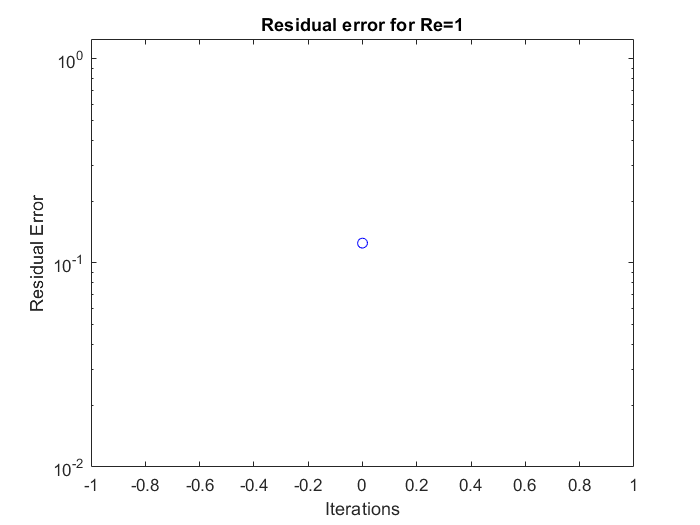

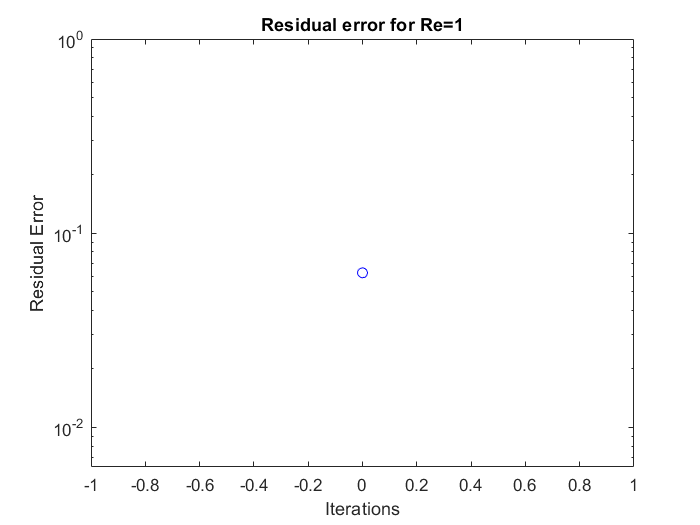

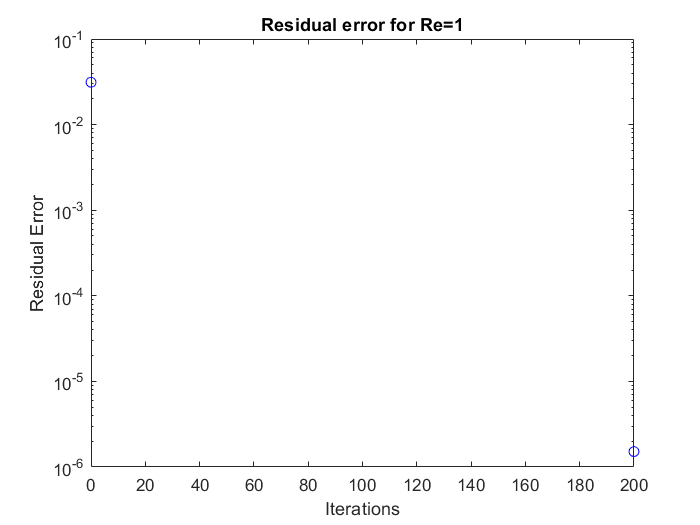

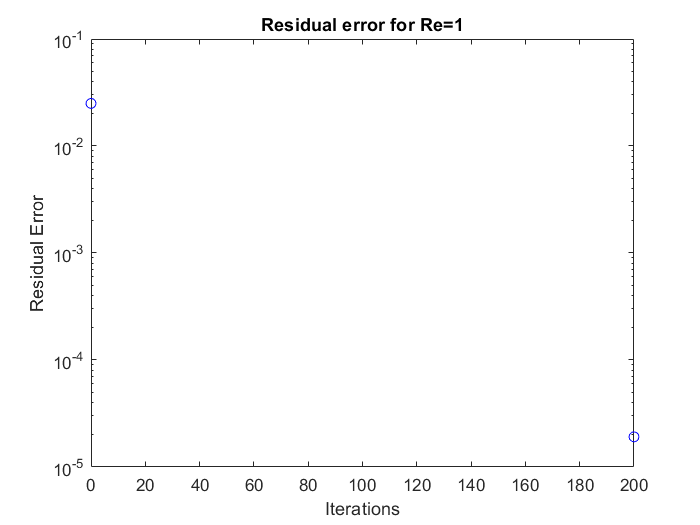

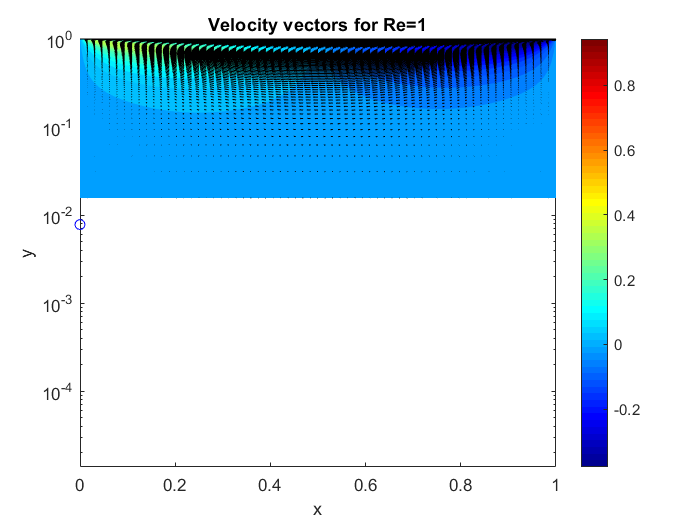

if k==1 && l==5
   x_dom = ((1:N(5))-1).*(1/(N(5)-1));
   y_dom = 1-((1:N(5))-1).*(1/(N(5)-1));
   [X,Y] = meshgrid(x_dom,y_dom);
   figure(k);
   contourf(X,Y,u1_true{5}, 20, 'LineStyle', 'none')
   colorbar
   colormap('jet')
   title('Horizontal velocity contour for Re=1')
   xlabel('x')
   ylabel('y')
   figure(k+1);
   contourf(X,Y,v1_true{5}, 20, 'LineStyle', 'none')
   title('Vertical velocity contour for Re=1')
   colorbar
   colormap('jet')
   xlabel('x')
   ylabel('y')
   figure(k+2);
   hold on
   quiver(X, Y, u1_true{5}, v1_true{5}, 5, 'k')
   title('Velocity vectors for Re=1')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+3)
   hold on
   streamslice(X,Y,u1_true{5},v1_true{5})
   title('Velocity streamlines for Re=1')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+4)
   scatter([1/8 1/16 1/20 1/32], abs([(u1_true{2}((N(2)+1)/2,(N(2)+1)/2)-u1_true{1}((N(1)+1)/2,(N(1)+1)/2)) (u1_true{3}((N(3)+1)/2,(N(3)+1)/2)-u1_true{2}((N(2)+1)/2,(N(2)+1)/2)) (u1_true{4}((N(4)+1)/2,(N(4)+1)/2)-u1_true{3}((N(3)+1)/2,(N(3)+1)/2)) (u1_true{5}((N(5)+1)/2,(N(5)+1)/2)-u1_true{4}((N(4)+1)/2,(N(4)+1)/2))]))
   hold on
   set(gca,'xscale','log')
   set(gca,'YScale','log')
   xlabel('h')
   ylabel('Successive Error')
   title('successive error for Re=1')
end
if k==2 && l==5
   x_dom = ((1:N(5))-1).*(1/(N(5)-1));
   y_dom = 1-((1:N(5))-1).*(1/(N(5)-1));
   [X,Y] = meshgrid(x_dom,y_dom);
   figure(k+4);
   contourf(X,Y,u10_true{5}, 20, 'LineStyle', 'none')
   colorbar
   colormap('jet')
   title('Horizontal velocity contour for Re=10')
   xlabel('x')
   ylabel('y')
   figure(k+5);
   contourf(X,Y,v10_true{5}, 20, 'LineStyle', 'none')
   title('Vertical velocity contour for Re=10')
   colorbar
   colormap('jet')
   xlabel('x')
   ylabel('y')
   figure(k+6);
   hold on
   quiver(X, Y, u10_true{5}, v10_true{5}, 5, 'k')
   title('Velocity vectors for Re=10')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+7)
   hold on
   streamslice(X,Y,u10_true{5},v10_true{5})
   title('Velocity streamlines for Re=10')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+8)
   scatter([1/8 1/16 1/20 1/32], abs([(u10_true{2}((N(2)+1)/2,(N(2)+1)/2)-u10_true{1}((N(1)+1)/2,(N(1)+1)/2)) (u10_true{3}((N(3)+1)/2,(N(3)+1)/2)-u10_true{2}((N(2)+1)/2,(N(2)+1)/2)) (u10_true{4}((N(4)+1)/2,(N(4)+1)/2)-u10_true{3}((N(3)+1)/2,(N(3)+1)/2)) (u10_true{5}((N(5)+1)/2,(N(5)+1)/2)-u10_true{4}((N(4)+1)/2,(N(4)+1)/2))]))
   hold on
   set(gca,'xscale','log')
   set(gca,'YScale','log')
   xlabel('h')
   ylabel('Successive Error')
   title('successive error for Re=10')
end
if k==3 && l==5
   x_dom = ((1:N(3))-1).*(1/(N(3)-1));
   y_dom = 1-((1:N(3))-1).*(1/(N(3)-1));
   [X,Y] = meshgrid(x_dom,y_dom);
   figure(k+8);
   contourf(X,Y,u100_true{3}, 20, 'LineStyle', 'none')
   colorbar
   colormap('jet')
   title('Horizontal velocity contour for Re=100')
   xlabel('x')
   ylabel('y')
   figure(k+9);
   contourf(X,Y,v100_true{3}, 20, 'LineStyle', 'none')
   title('Vertical velocity contour for Re=100')
   colorbar
   colormap('jet')
   xlabel('x')
   ylabel('y')
   figure(k+10);
   hold on
   quiver(X, Y, u100_true{3}, v100_true{3}, 5, 'k')
   title('Velocity vectors for Re=100')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+11)
   hold on
   streamslice(X,Y,u100_true{3},v100_true{3})
   title('Velocity streamlines for Re=100')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+12)
   scatter([1/16 1/20 1/32 1/64], abs([(u100_true{2}((N(2)+1)/2,(N(2)+1)/2)-u100_true{1}((N(1)+1)/2,(N(1)+1)/2)) (u100_true{3}((N(3)+1)/2,(N(3)+1)/2)-u100_true{2}((N(2)+1)/2,(N(2)+1)/2)) (u100_true{4}((N(4)+1)/2,(N(4)+1)/2)-u100_true{3}((N(3)+1)/2,(N(3)+1)/2)) (u100_true{5}((N(5)+1)/2,(N(5)+1)/2)-u100_true{4}((N(4)+1)/2,(N(4)+1)/2))]))
   hold on
   set(gca,'xscale','log')
   set(gca,'YScale','log')
   xlabel('h')
   ylabel('Successive Error')
   title('successive error for Re=100')
end
if k==4 && l==5
   x_dom = ((1:N(2))-1).*(1/(N(2)-1));
   y_dom = 1-((1:N(2))-1).*(1/(N(2)-1));
   [X,Y] = meshgrid(x_dom,y_dom);
   figure(k+12);
   contourf(X,Y,u500_true{2}, 20, 'LineStyle', 'none')
   colorbar
   colormap('jet')
   title('Horizontal velocity contour for Re=500')
   xlabel('x')
   ylabel('y')
   figure(k+13);
   contourf(X,Y,v500_true{2}, 20, 'LineStyle', 'none')
   title('Vertical velocity contour for Re=500')
   colorbar
   colormap('jet')
   xlabel('x')
   ylabel('y')
   figure(k+14);
   hold on
   quiver(X, Y, u500_true{2}, v500_true{2}, 5, 'k')
   title('Velocity vectors for Re=500')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+15)
   hold on
   streamslice(X,Y,u500_true{2},v500_true{2})
   title('Velocity streamlines for Re=500')
   xlim([0 1])
   ylim([0 1])
   xlabel('x')
   ylabel('y')
   figure(k+16)
   scatter([1/120 1/130 1/140 1/150], abs([(u500_true{2}((N(2)+1)/2,(N(2)+1)/2)-u500_true{1}((N(1)+1)/2,(N(1)+1)/2)) (u500_true{3}((N(3)+1)/2,(N(3)+1)/2)-u500_true{2}((N(2)+1)/2,(N(2)+1)/2)) (u500_true{4}((N(4)+1)/2,(N(4)+1)/2)-u500_true{3}((N(3)+1)/2,(N(3)+1)/2)) (u500_true{5}((N(5)+1)/2,(N(5)+1)/2)-u500_true{4}((N(4)+1)/2,(N(4)+1)/2))]))
   hold on
   set(gca,'xscale','log')
   set(gca,'YScale','log')
   xlabel('h')
   ylabel('Successive Error')
   title('successive error for Re=500')
end
end
end

## 5.Validation by Ghia et al. study[2]

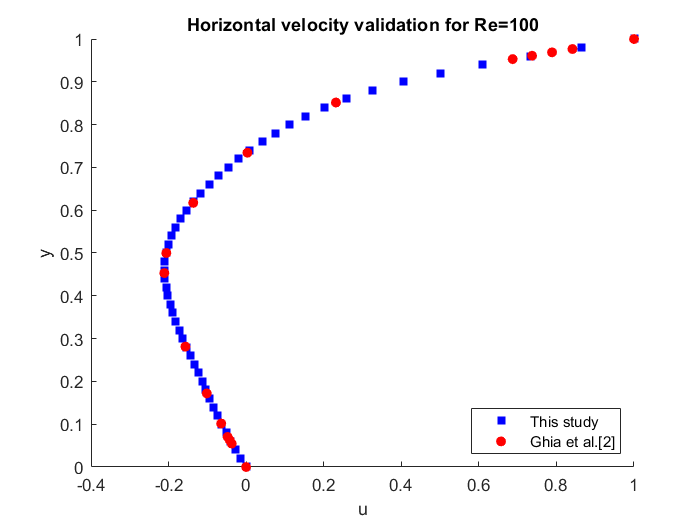

% Centreline u,v validation - Comparison with Ghia et al. study[2] (table 1 and table 2)
y_validation=0:0.02:1;
x_validation=0:0.02:1;
figure(21);
scatter(u100_true{2}(:,26),1-y_validation,'s','filled','b')
figure(22);
scatter(x_validation,v100_true{2}(26,:),'s','filled','b')
y_Ghia = [0 0.0547 0.0625 0.0703 0.1016 0.1719 0.2813 0.4531 0.5 0.6172 0.7344 0.8516 0.9531 0.9609 0.9688 0.9766 1];
u_Ghia = [0 -0.03717 -0.04192 -0.04775 -0.06434 -0.10150 -0.15662 -0.21090 -0.20581 -0.13641 0.00332 0.23151 0.68717 0.73722 0.78871 0.84123 1];
x_Ghia = [0 0.0625 0.0703 0.0781 0.0938 0.1563 0.2266 0.2344 0.5 0.8047 0.8594 0.9063 0.9453 0.9531 0.9609 0.9688 1];
v_Ghia = [0 0.09233 0.10091 0.10890 0.12317 0.16077 0.17507 0.17527 0.05454 -0.24533 -0.22445 -0.16914 -0.10313 -0.08864 -0.07391 -0.05906 0];
figure(21); hold on
scatter(u_Ghia, y_Ghia, 'o','filled','r')
title('Horizontal velocity validation for Re=100')
xlabel('u')
ylabel('y')
legend('This study', 'Ghia et al.[2]', 'location', 'southeast')
hold off

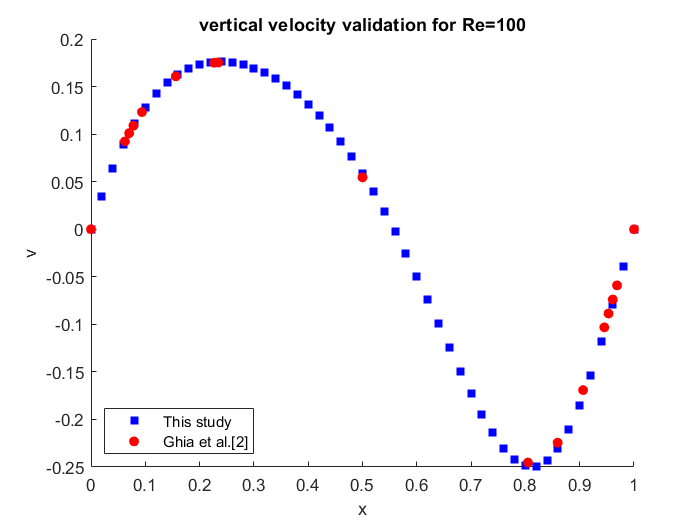

figure(22); hold on
scatter(x_Ghia, v_Ghia, 'o', 'filled','r')
title('vertical velocity validation for Re=100')
xlabel('x')
ylabel('v')
legend('This study', 'Ghia et al.[2]', 'location', 'southwest')
hold off

toc

Elapsed time is 258.518539 seconds.


#### Velocity vectors for Re=500 in 61*61 grid(to see vectors better)

% x_dom500 = ((1:61)-1).*h*2;
% y_dom500 = 1-((1:61)-1).*h*2;
% [X500,Y500] = meshgrid(x_dom500,y_dom500);
% for i=1:61
%     for j=1:61
% U_true{1}(i,j)=u500_true{4}(2*i-1,2*j-1);
% V_true{1}(i,j)=v500_true{4}(2*i-1,2*j-1);
%     end
% end
% figure(100)
% quiver(X500, Y500, U_true{1}, V_true{1}, 5, 'k')
%    title('Velocity vectors for Re=500')
%    xlim([0 1])
%    ylim([0 1.2])
%    xlabel('x')
%    ylabel('y')